format long
tol = 10^(-10)

tol =      1.000000000000000e-10


nmax = 100;

## 3 Implizite Einschrittverfahren - Leonard Berresheim

### 3.1 Entwicklung

1. Bei einer steifen Differenzialgleichung handelt es sich um eine Gleichung, für die gilt, dass bei bestimmten numerischen Methoden der Störfaktor am Ausgang besonders groß ist, wenn die Schrittweite nicht sehr klein gewählt wird.

2. Geben sind das implizite Euler-Verfahren


$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 1\right)$$


und die implizite Trapezregel


$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +\frac{h}{2}\;\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 2\right)$$


Wir setzten nun


$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 3\right)$$


ein in $\left(a\ldotp 1\right)$


$${\mathbf{y}}^{\left(i\right)} +\mathbf{z}={\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 4\right)\;$$


und in $\left(a\ldotp 2\right)$


$${\mathbf{y}}^{\left(i\right)} +\mathbf{z}={\mathbf{y}}^{\left(i\right)} +\frac{h}{2}\;\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 5\right)\;$$


Formulieren wir nun beides als Nullstellenproblem für $\mathbf{z}$ erhalten wir


$${\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 6\right)\;\;\;$$


und


$${\mathbf{F}}_{\textrm{trapez}} \left(\mathbf{z}\right)=\frac{h}{2}\;\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\right\rbrack -\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 7\right)\;\;\;$$


3. Die Jacobi-Matrix in Abhängigkeit von $D_y \mathbf{f}$ sieht wie folgt aus


$${D\;\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)={h\;D}_{\left(y\right)} \mathbf{f}\left(t_{i+1} ,y^{\left(i\right)} +z\right)-\overset{~}{D} \mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 8\right)$$


für das implizite Euler-Verfahren und


$${D\;\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=\frac{h}{2}\left\lbrack {\;D}_{\left(y\right)} \mathbf{f}\left(t_i ,y^{\left(i\right)} \right)+{h\;D}_{\left(y\right)} \mathbf{f}\left(t_{i+1} ,y^{\left(i\right)} +z\right)\right\rbrack -\overset{~}{D} \mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 9\right)$$


für das implizite Trapez-Verfahren,

wobei


$$D_y \mathbf{f}=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial y_1 } & \frac{\partial f_1 }{\partial y_2 } & \cdots  & \frac{\partial f_1 }{\partial y_n }\\
\frac{\partial f_2 }{\partial y_1 } & \frac{\partial f_2 }{\partial y_2 } & \cdots  & \frac{\partial f_2 }{\partial y_n }\\
\vdots  & \vdots  & \; & \vdots \\
\frac{\partial f_n }{\partial y_1 } & \frac{\partial f_n }{\partial y_2 } & \cdots  & \frac{\partial f_n }{\partial y_n }
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 10\right)$$


und 


$$\overset{~}{D} \mathbf{z}=\left\lbrack \begin{array}{cccc}
1 & 0 & \cdots  & 0\\
0 & 1 & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & 0\\
0 & \cdots  & 0 & 1
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 11\right)$$


4. Die Routinen **F_euler** & **F_trapez** wurden implementiert

*(siehe F_euler.m & F_trapez.m)*

5. Die Routinen **impl_euler** & **impl_trapez **wurden implementiert

*(siehe impl_euler.m & impl_trapez.m)*

6. Sei das Anfangswertproblem


$$y^{\prime } =-y\;\textrm{mit}\;y\left(0\right)=1\;\textrm{und}\;t\in \left\lbrack 0,1\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 1\right)$$


Mit Hilfe von Wolframalpha ehällte man für $\left(b\ldotp 1\right)$ die Lösung


$$y^{\prime } \left(x\right)={c_1 e}^{-x} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 2\right)$$


Es wurde die Routine **max_abs_err **implementiert um für eine bestimmte Funktion und einen bestimmten Wert für **n** den maximalen absoluten Fehler zu bestimmen.

*(siehe max_abs_err.m)*

Diese Routine wird nun auf $\left(b\ldotp 1\right)$ angewendet um die Ordnung der beiden Verfahren (Euler & Trapez) zu bestimmen.

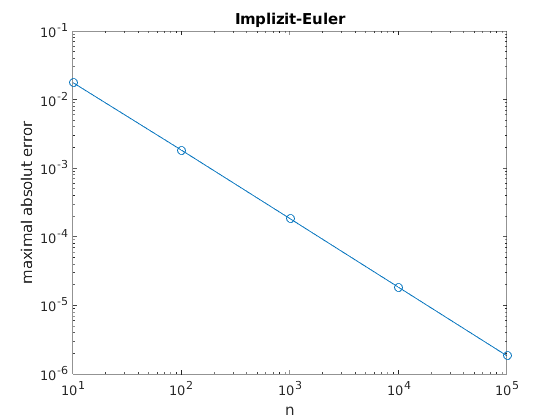

tspan = [0,1];
n= 10.^(1:5);
ya = 1;
f = @(t,y) -y;
df = @(t,y) -1;
f_loesung = @(x) exp(-x);
max_error = max_abs_err(@(n) impl_euler(f,tspan,ya,n,df,tol,nmax), n, f_loesung);
loglog(n, max_error, "-o")
title("Implizit-Euler")
xlabel("n")
ylabel("maximal absolut error")

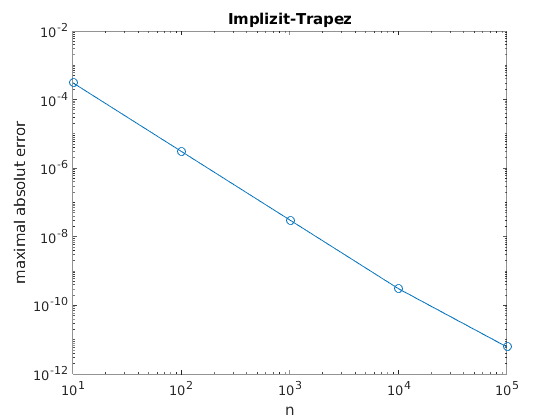

max_error = max_abs_err(@(n) impl_trapez(f,tspan,ya,n,df,tol,nmax), n, f_loesung);
loglog(n, max_error, "-o")
title("Implizit-Trapez")
xlabel("n")
ylabel("maximal absolut error")

7. Wir testen nun die Routinen **F_euler **und **F_trapez** mit folgendem System von Anfangswertproblemen


$${\mathbf{y}}^{\prime } =\left\lbrack \begin{array}{c}
t\;y_1 -3y_2 \\
3y_1 -t^2 y_2 
\end{array}\right\rbrack ;\mathbf{y}\left(0\right)=\left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack ;t=\left\lbrack 0,10\right\rbrack ;h=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 1\right)$$


Um zu bestimmen ob die Routinen richtige Ergebnisse liefern, wird als referenz Lösung die von Matlab bereitgestellte Routine ode45 verwendet.

n = 10^(2);
tspan = [0,1]

tspan =      0     1


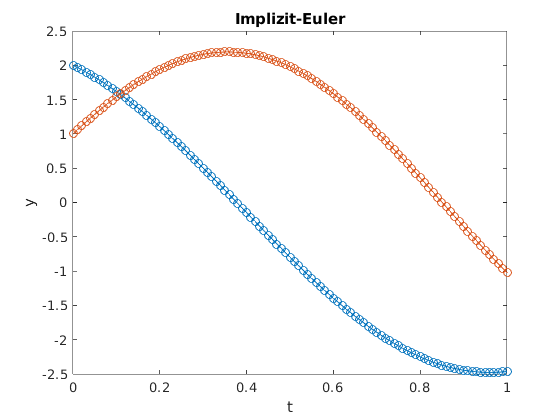

ya = [2;1];
f = @(t,y) [t*y(1)-3*y(2);3*y(1)-((t^2)*y(2))];
df = @(t,y) [t,-3;3,-(t^2)];
[t,y_out] = impl_euler(f,tspan,ya,n,df,tol,nmax);
plot(t,y_out, '-o')
title("Implizit-Euler")
xlabel("t")
ylabel("y")

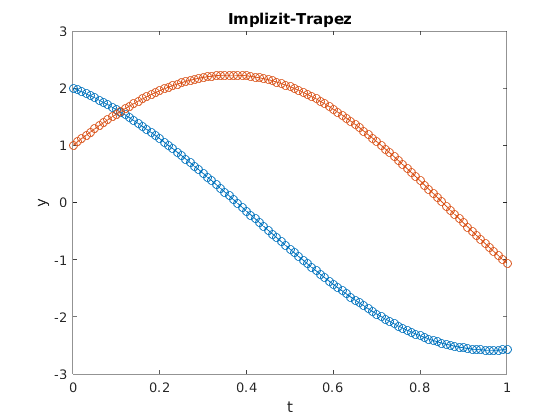

[t,y_out] = impl_trapez(f,tspan,ya,n,df,tol,nmax);
plot(t,y_out, '-o')
title("Implizit-Trapez")
xlabel("t")
ylabel("y")

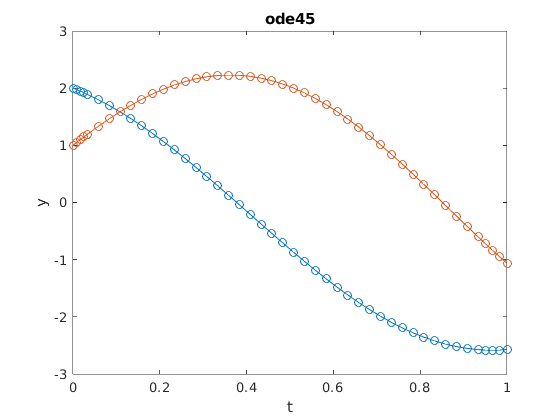

[t,y_out] = ode45(f,tspan,ya);
plot(t,y_out, '-o')
title("ode45")
xlabel("t")
ylabel("y")

### 3.2 Anwendung

1. Wir formulieren die Gleichung (9) aus der Aufgabenstellung  als


$${\mathbf{y}}^{\prime } =\mathbf{f}\left(t,\mathbf{y}\right)=\left\lbrack \begin{array}{c}
-0\ldotp 04y_1 +{10}^4 y_2 y_3 \\
0\ldotp 04y_1 -{10}^4 y_2 y_3 -3\cdot {10}^7 y_2^2 \\
3\cdot {10}^7 y_2^2 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(f\ldotp 1\right)\;\;\;\;$$


mit $t\in \left\lbrack 0,~\right\rbrack ,\;\mathbf{y}\left(0\right)=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack \;$

2. Es wurde nun **f_chem** implementiert

*(siehe f_chem.m)*

3. Es wird die Jacobi-Matrix von ${\mathbf{f}}_{\textrm{chem}}$bezüglich $\mathbf{y}$ berechnet:


$$D_y {\mathbf{f}}_{\textrm{chem}} \left(t,y\right)=\left\lbrack \begin{array}{ccc}
-0\ldotp 04 & {10}^4 y_3  & {10}^4 y_2 \\
0\ldotp 04 & -{10}^4 y_3 -6\cdot {10}^7 y_2  & -{10}^4 y_2 \\
0 & 3\cdot {10}^7  & 0
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(f\ldotp 2\right)$$


4. Es wurde **f_chem_jac **implementiert

*(siehe f_chem_jac.m)*

tspan = [0,10];
ya = [1;0;0];
f = @(t,y) [-0.04*y(1)+10^4*y(2)*y(3);
           0.04*y(1)-10^4*y(2)*y(3)-3*10^7*y(2)^2;
           3*10^7*y(2)^2];

Explizit Euler:

Implizit Euler:

n = 4250;
max_error = max_abs_error2(@(n) impl_euler(@f_chem,tspan,ya,n,@f_chem_jac,tol,nmax),n)

max_error =      2.911379079294230e-05


ode45:

% [t,y_out] = ode45(f,tspan,ya);
% plot(t,y_out, '-o')